# EXERCISE #4 Model Multi-Link Operation (MLO) in Wi-Fi 7 Networks

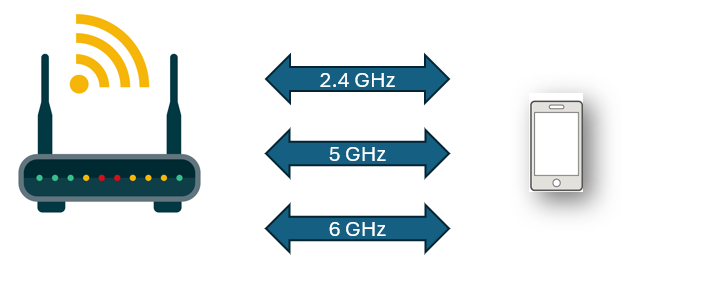

WLAN Network with one AP and one STA 

AP and STA Multi-Link Devices (MLDs)

**In this exercise, You will learn how to **

- Create and configure a Wi-Fi 7 network with one AP MLD and two STA MLDs.  

- Visualize packet communication in time and frequency domains. 

- Plot network KPIs such as MAC throughput 

- Capture APP, MAC, and PHY statistics for each node.

Perform cleanup by closing previously opened windows and figures. 

clear all;
all_figs = findall(0, 'type', 'figure');close(all_figs);

- Initialize the random number generator for reproducibility

- Set the simulation time

- Initialize the network simulator

- Launch the wireless network viewer to visualize the network during simulation

- Define AP and STA position 

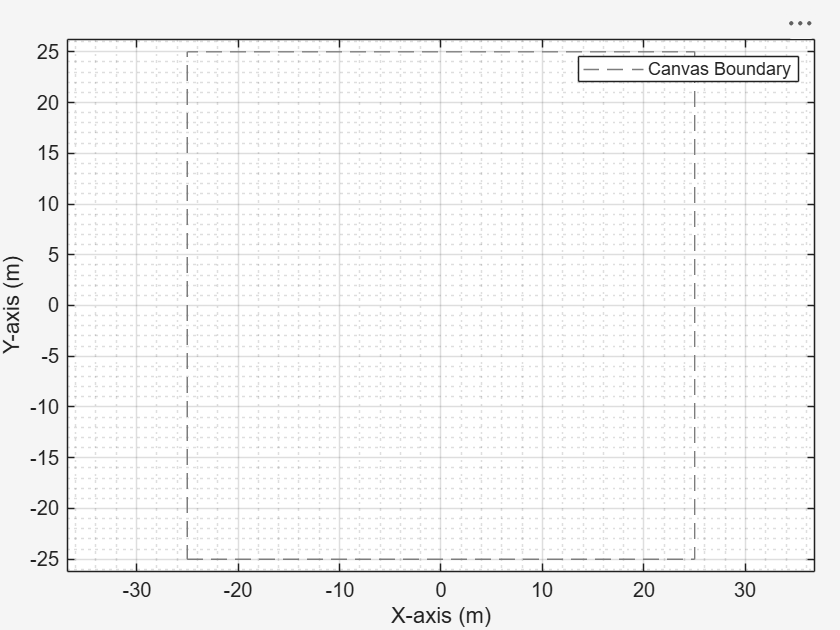

rng(1,"twister");
TU              = 1024e-6;
simulationTime  = 100*TU;
networkSimulator = wirelessNetworkSimulator.init;
networkViewerObj = wirelessNetworkViewer(CanvasSize=[50 50 0]);

# Task 1/7 Configure a Wi-Fi-7 Access Point (AP) Link

**Description of the task**

A Wi-Fi 7 Access Point (AP) can communicate over multiple links. A link is a combination of a frequency band and a channel.

Typical combinations:

- 5 GHz + 6 GHz 

- 2.4 GHz + 5 GHz 

- 2.4 GHz + 5 GHz + 6 GHz

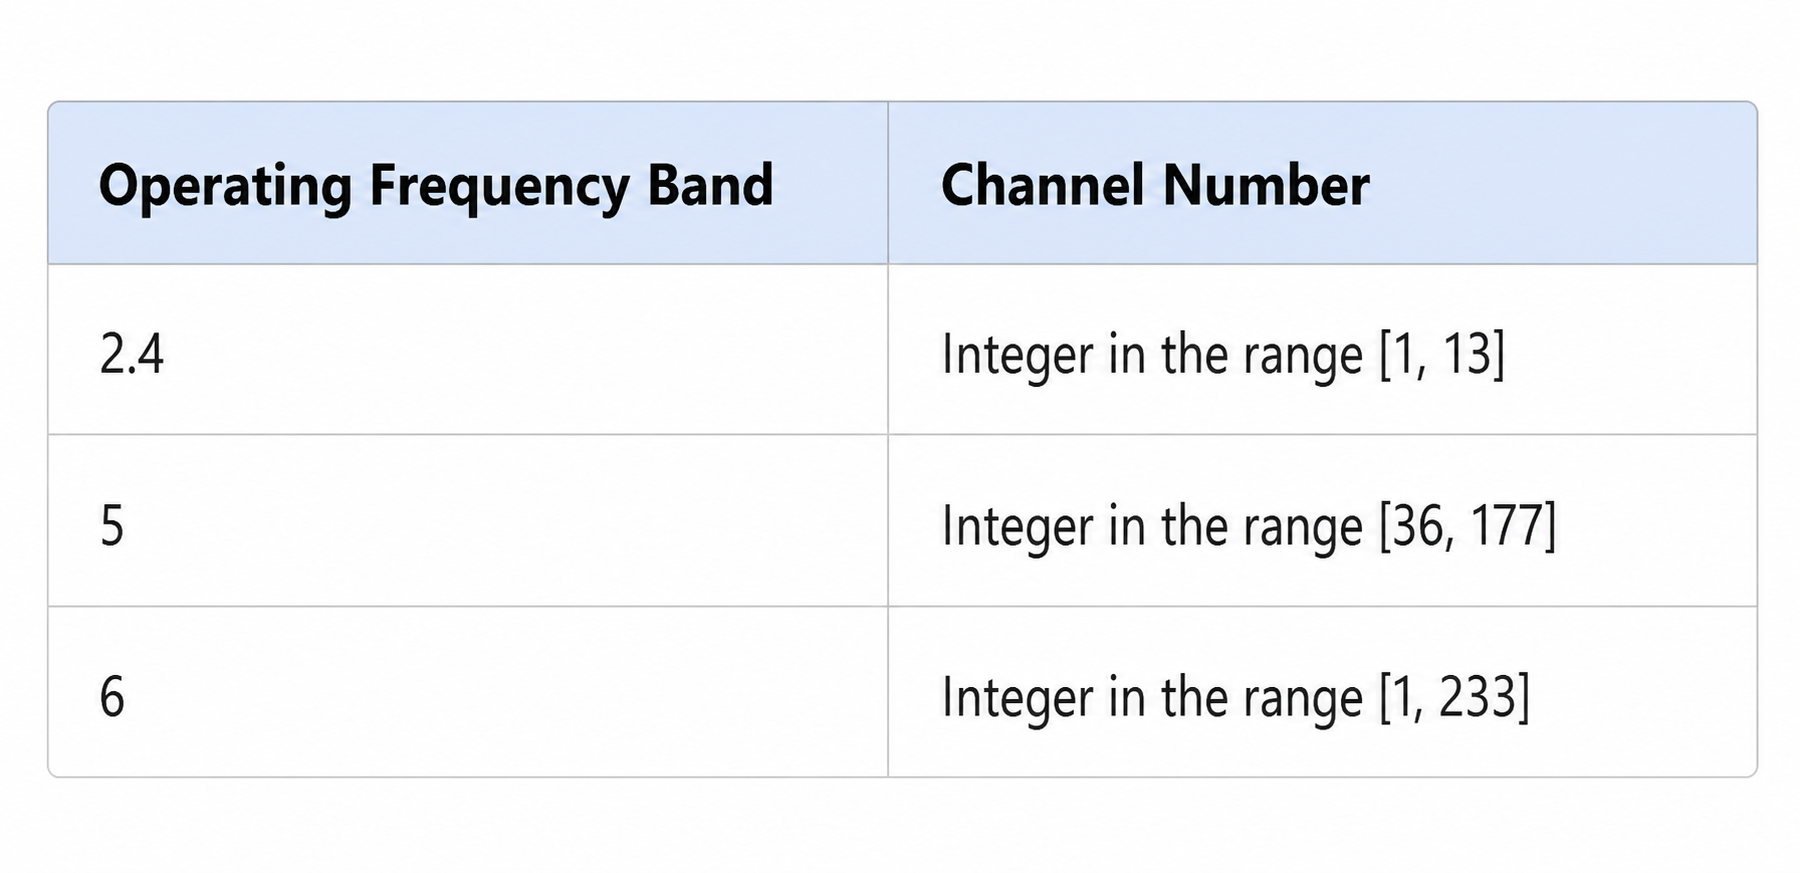

[WLAN Valid Channel Number and Bandwidth Combinations](https://www.mathworks.com/help/releases/R2026a/wlan/ug/valid-channel-number-and-bandwidth-combinations.html)

**Instructions to complete the task**

Use wlanLinkConfig() function to configure the AP link

Write configuration in a variable named "apLinkCfg"

Hint: Type "doc wlanLinkConfig" in the MATLAB Command Window, and see the "Syntax" section.

Pass the following as arguments 

- "BandAndChannel",bandAndChannelValues

- "NumTransmitAntennas",3

- "MCS",mcs

- "ChannelBandwidth",bandwidth

bandAndChannelValues = [2.4 1; 5 36; 6 5];
mcs = 0;
bandwidth = 20e6;

% <enter code below>
% apLinkCfg  = 

# Task 2/7 Configure a Wi-Fi-7 Station (STA) Link 

**Instructions to complete the task**

Use wlanLinkConfig() function to configure the STA link

Write configuration in a variable named "staLinkCfg"

Hint: Type "doc wlanLinkConfig" in the MATLAB Command Window, and see the "Syntax" section.

Pass the following as arguments 

- "BandAndChannel",bandAndChannelValues

- "NumTransmitAntennas",1

- "MCS",mcs

- "ChannelBandwidth",bandwidth

% <enter code below>
% staLinkCfg  = 

# Task 3/7 Configure a Wi-Fi-7 Access Point(AP) Device 

**Description of the task**

Create a Simultaneous Transmit and Receive (STR) WLAN AP.

NSTR and EMLMR support are not yet available.

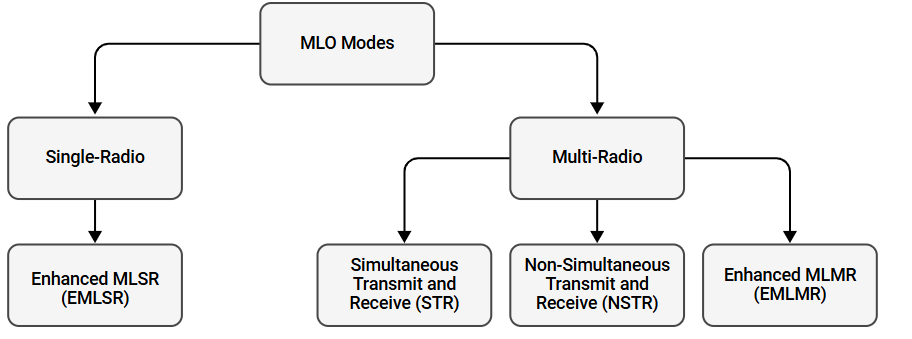

**Instructions to complete the task**

Use wlanMultilinkDeviceConfig() function to configure the AP Device

Write configuration in a variable named "apMLDCfg"

Hint: Type "doc wlanMultilinkDeviceConfig" in the MATLAB Command Window, and see the "Syntax" section.

Pass the following as arguments 

- "Mode","AP"

- "LinkConfig",apLinkCfg

% <enter code below>
% apMLDCfg = 

# Task 4/7 Configure a Wi-Fi-7 Station(STA) Device 

**Description of the task**

- Wi-Fi 7 introduces **Enhanced Multi-Link Single Radio (EMLSR)**, an improved single-radio MLD mode. 

- In EMLSR mode, the STA MLD uses multiple receive chains to monitor multiple active links simultaneously. 

- EMLSR improves throughput and reduces latency while maintaining a single transmit radio architecture. 

- Many single-radio MLDs with at least 2×2 MIMO capability can achieve performance close to dual-radio MLDs.

**Instructions to complete the task**

Use wlanMultilinkDeviceConfig() function to configure the AP Device

Write configuration in a variable named "staMLDCfg"

Hint: Type "doc wlanMultilinkDeviceConfig" in the MATLAB Command Window, and see the "Syntax" section.

Pass the following as arguments 

- Mode="STA"

- LinkConfig=staLinkCfg

- EnhancedMultilinkMode="EMLSR"

% <enter code below>
% staMLDCfg = 

# Task 5/7: Create a WLAN Access Point (AP)

**Description of the task**

Configure the abstraction level of the MAC and PHY, and set the position of the access point.

**PHY Options**

- **Full PHY (IQ samples)**

- Supports waveform generation and decoding 

- **Abstracted PHY**

- Uses PER tables based on the 802.11ax evaluation methodology 

- Enables PHY abstraction for system-level simulation 

- **Pass-through PHY (MAC calibration)**

- No PHY is modeled 

- Interfered packets are dropped 

**MAC Options**

- **Full MAC**

- EDCA MAC with full MAC frame generation 

- **Abstracted MAC**

- EDCA MAC without MAC frame generation 

**Note / Implication**

- Use **Full MAC** if you want to capture WLAN packets in PCAP files and analyze them in Wireshark.

- All nodes on the network must have same MAC and PHY abstraction

- You can't set Abstracted MAC and full PHY

**Instructions to complete the task**

Use wlanNode() function to instantiate the AP using the configuration you have just created

Hint: Type "doc wlanNode" in the MATLAB Command Window, and see the "Syntax" section.

Name the variable "AP"

Pass the following as arguments 

- "Position",[0 0 0]

-  Name="AP"

-  MACModel=macmodel

-  PHYModel=phymodel

-  DeviceConfig=apMLDCfg

macmodel = "full-mac";
phymodel = "full-phy";
AP_pos= [0, 0, 0];

% <enter code below>
% apMLD = 

#### Visualize the Access Point in the Network Viewer 

Add node to the network viewer for visualization

addNodes(networkViewerObj,apMLD,Type="AP")

# Task 6/7: Create a WLAN Access Point (AP)

**Instructions to complete the task**

Use wlanNode() function to instantiate the AP using the configuration you have just created

Hint: Type "doc wlanNode" in the MATLAB Command Window, and see the "Syntax" section.

Name the variable "AP"

Pass the following as arguments 

- "Position",[0 0 0]

-  Name="STA"

-  MACModel=macmodel

-  PHYModel=phymodel

-  DeviceConfig=apMLDCfg

% <enter code below>
% staMLD = 

#### Visualize the station in the Network Viewer 

Add node to the network viewer for visualization 

addNodes(networkViewerObj,staMLD,Type="STA")

**Associate the AP with the STA to create a Basic Service Set (BSS).**

associateStations(apMLD,staMLD,"FullBufferTraffic","on");

#### **Add nodes to the network **

Calling addNodes adds nodes to the simulator

nodes = [apMLD staMLD];
addNodes(networkSimulator,nodes)

#### Enable packet visualization, **node performance visualization, and PCAP capture **

- Use the **wirelessTrafficViewer** object to monitor wireless nodes 

- View node state transitions over time 

- See channel occupancy for each node 

- Visualize packet transmissions over time 

packetVisObj = wirelessTrafficViewer;
addNodes(packetVisObj,nodes); 

**Node performance visualization**

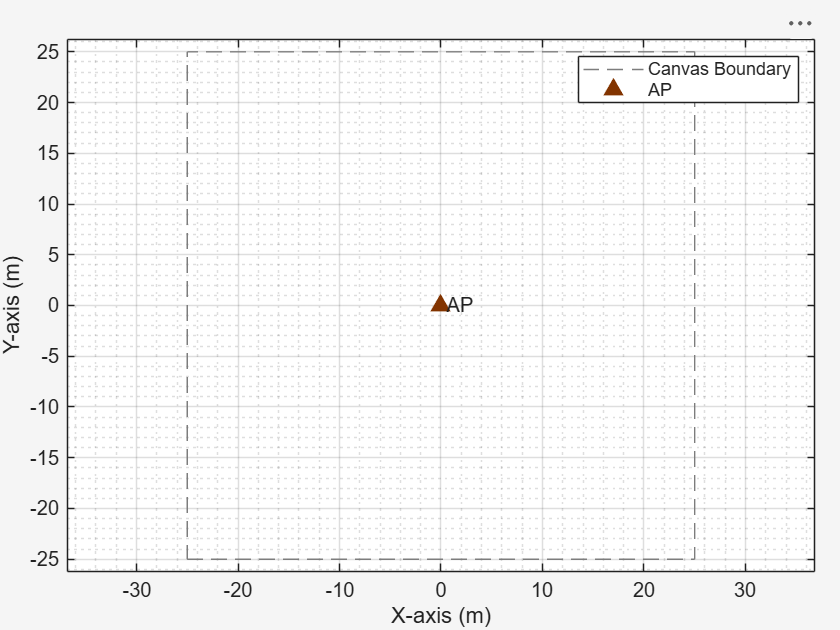

perfViewerObj = helperPerformanceViewer(nodes,simulationTime);

**Enable PCAP capture**

The wlanPCAPWriter saves generated and received WLAN MAC packets to a PCAP or PCAPNG file.

capturePacketsObj =wlanPCAPWriter(Node=nodes, RadiotapPresent=1);

# Task 7/7: Run the simulation

Runs the discrete-event simulator in MATLAB to execute the network model.

**Instructions to complete the task**

Use run() function to run the model    

Type `doc wirelessnetworksimulator.run` in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- networkSimulator

- simulationTime

% <enter code below>


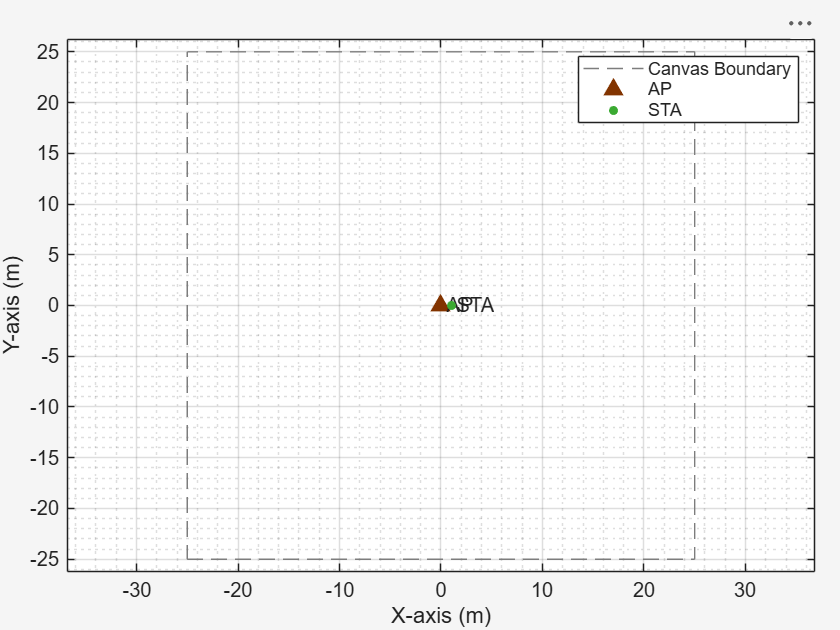

plotNetworkStats(perfViewerObj)

stats = statistics(nodes,"all");

Calculate the MAC throughput (in Mbps) at the STA1 node and at each link in the STA1 node by using the `throughput`  function 

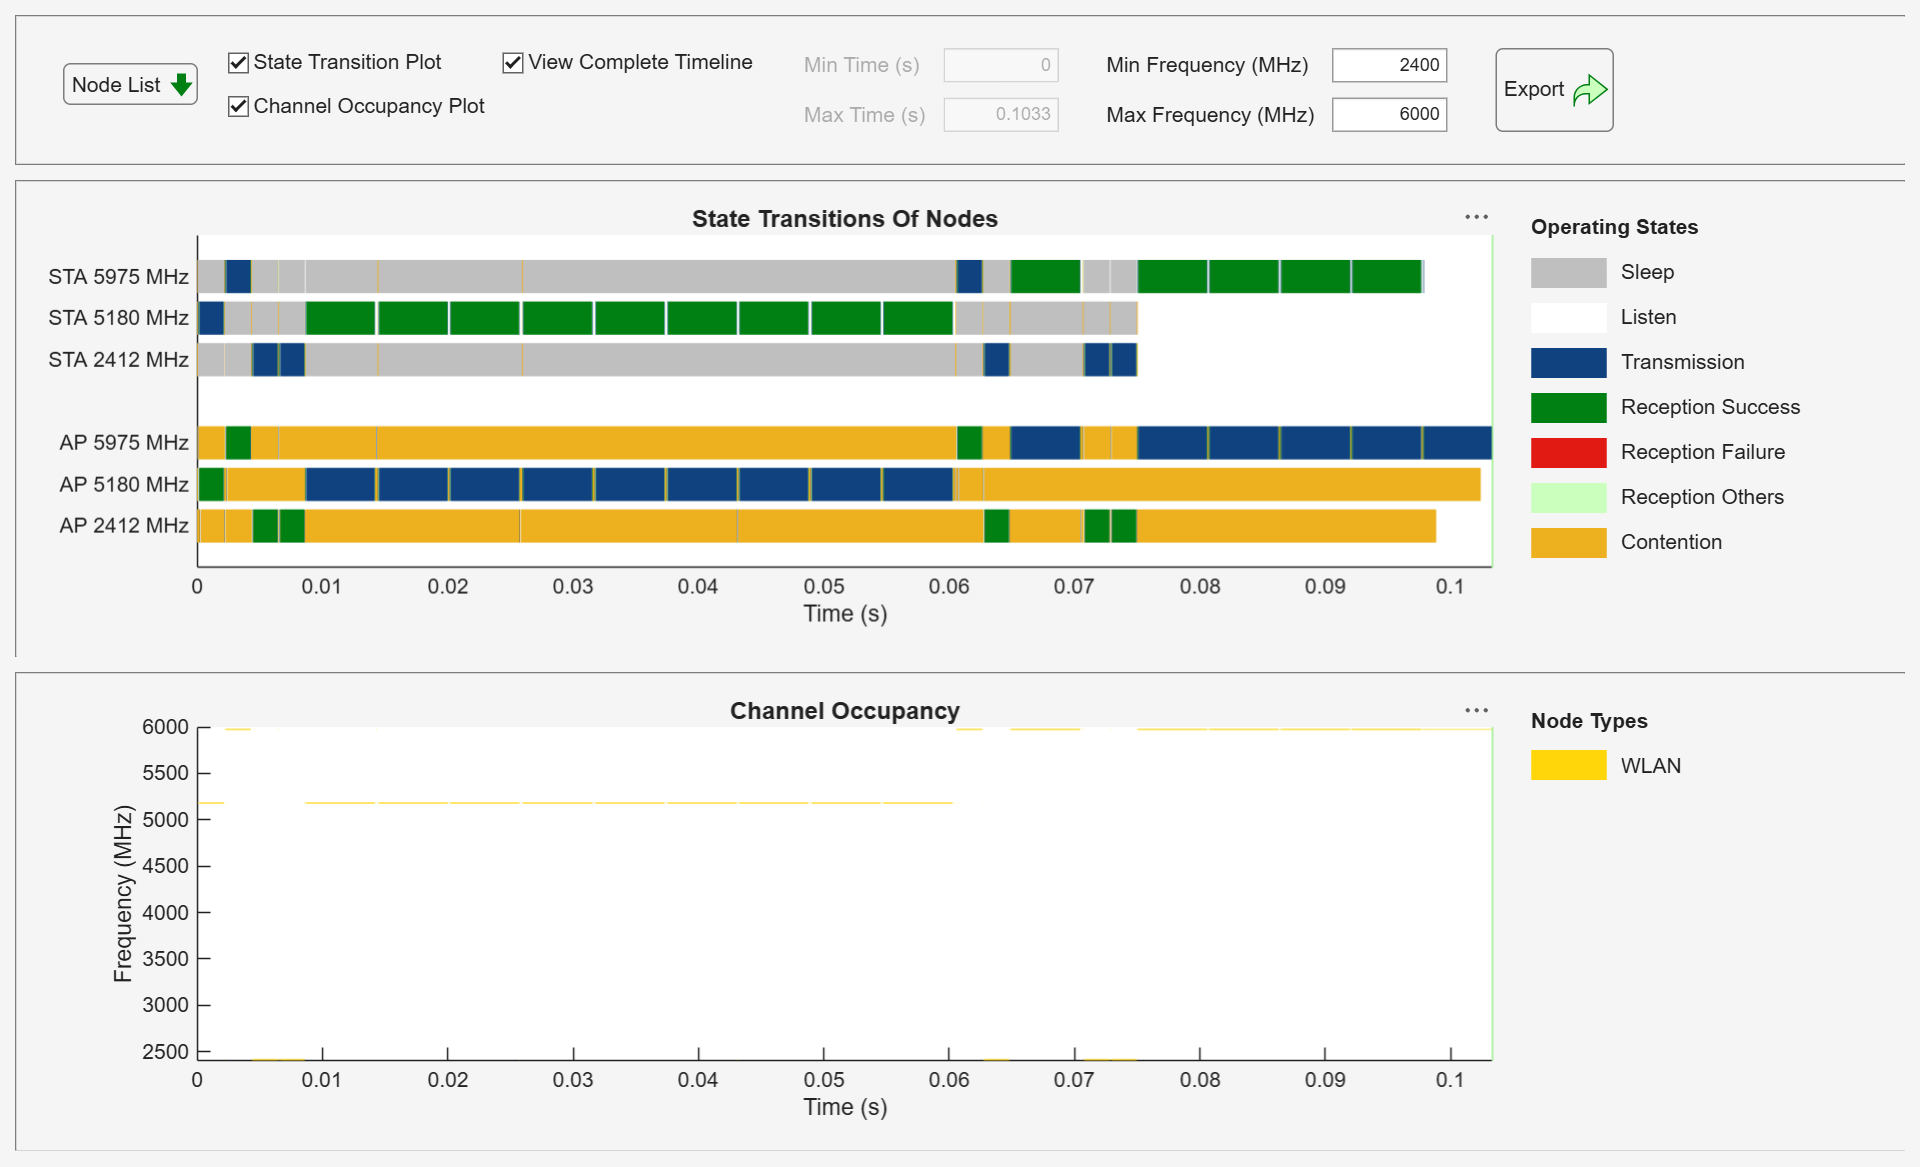

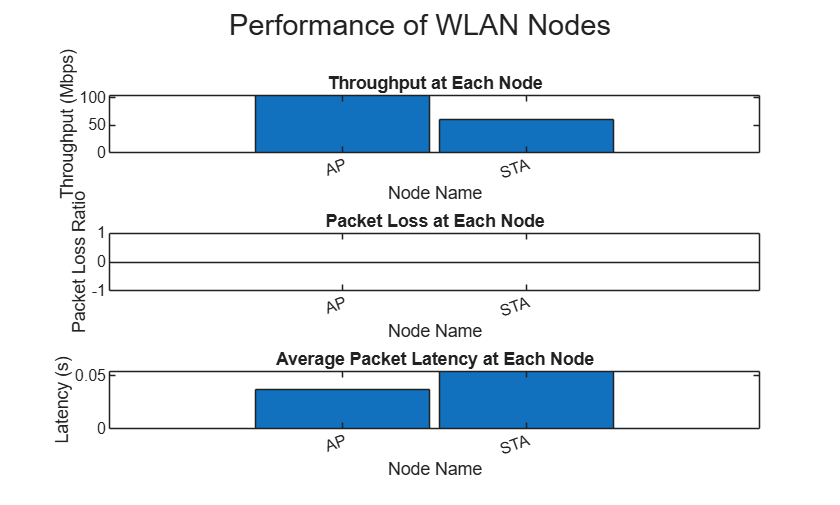

staMLDThroughput = 60.0000

staLink1Throughput = 37.5000

staLink2Throughput = 7.5000

staLink3Throughput = 15.0000

staMLDThroughput = throughput(perfViewerObj,staMLD(1).ID)
staLink1Throughput = throughput(perfViewerObj,staMLD(1).ID,LinkID=1)
staLink2Throughput = throughput(perfViewerObj,staMLD(1).ID,LinkID=2)
staLink3Throughput = throughput(perfViewerObj,staMLD(1).ID,LinkID=3)
delete(capturePacketsObj);